# Youla parameterization - Control of stable continuous processes.

# Advanced topic

This live script needs the control toolbox. 

The script goes through the main principles of control of stable continuous processes using Youla parameterization and shows its application through examples.  

### Similar files and the toolbox

See website below for more control concepts.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by László Keviczky and Ruth Bars, Budapest University of Technology and Economics                    

**Reference****: Control Engineering **and** Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

The related website has been developed by J.A. Rossiter, University of Sheffield                             

## Table of contents

- Mathematical background

- Controller design 

- Examples

                Example 1. Youla parameterised control of a first order system with dead  time 

                Example 2. Youla parameterised control of a third order system

                Example 3. Youla parameterised control of a non-minimum phase process

          Summary

### 1. Mathematical background

This script assumes the following block diagram with the system given by its transfer function* G(s)* and the compensator given by transfer function *M(s)*,  *r* is the reference signal, *u* is the control signal and *y* is the output signal,  *yni* and *yno* are the input and output disturbances, respectively and *yz* is the measurement noise. 

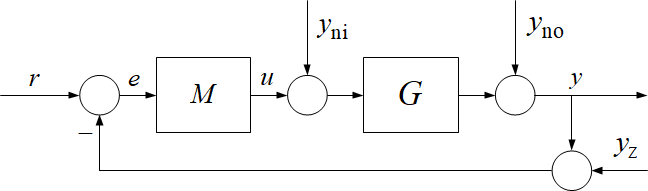

With appropriately designed compensator (controller) the closed loop control system should ensure reference signal tracking and disturbance rejection and also attenuation of the effect of the measurement noise.

This livescript shows simple design techniques for the compensator *M(s). *As it will be seen the compensator can be designed in open loop ensuring good reference signal tracking and disturbance rejection is realised with IMC (Internal Model Control).

### 1.1 The YOULA parameter

The relationship between the control signal *u *and the reference signal* r* supposing no disturbances is given by the following relationship: 


$$\frac{U\left(s\right)}{R\left(s\right)}=\frac{M}{1+\textrm{GM}}=Q$$
      

The transfer function *Q* is called the YOULA parameter.

The resulting transfer function between the output signal y and the reference signal r is  *T*=*QG. * If *G* is stable, any stable *Q* ensures a stable closed loop control circuit. The series *M*(*s*) controller can be expressed with the YOULA parameter as:

$M\left(s\right)=\frac{Q}{1-\textrm{QG}}$.

**Remark: **The resulting closed-loop transfer function $T=\textrm{QG}$ is linear in the parameter *Q*, while it is nonlinearly related to the series controller *M (e.g. *typically $T=\frac{\textrm{GM}}{1+\textrm{GM}}$). Therefore the design of parameter *Q* may be simpler than the design of the series controller *M*.

The sensitivity function is given as:


$$S\left(s\right)=\frac{1}{1+\textrm{MG}}=1-\textrm{QG}$$


The sensitivity function shows how the output disturbance affects the output signal, or similarly how the error signal is affected by the reference signal. If the frequency amplitude of the sensitivity function shows amplification in a given frequency range then the effect of the disturbance in this frequency range will be significant. This effect should be decreased.

The relationship between any input signal (i.e. *r, yni, yno, yz*) and any output signal (i.e. *y, u, e*) can also be given in terms of the Q parameter. Considering only the output disturbance $y_n =y_{\mathrm{no}}$, the control signal, the error signal and the output signal can easily be calculated as:


$$\left\lbrack \begin{array}{c}
u\\
e\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
Q & -Q\\
1-\textrm{QG} & -\left(1-\textrm{QG}\right)\\
\textrm{QG} & 1-\textrm{QG}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_{\textrm{ni}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
Q & -Q\\
S & -S\\
T & S
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_{\textrm{ni}} 
\end{array}\right\rbrack$$


Again the core point point is the linear dependence upon Q for each of these transferences, thus if we can design Q directly, then we can design these transferences directly.

### 1.2 The control structure with the YOULA parameter

A simplified block diagram of the control system with the Q parameter can be represented by the following figure.

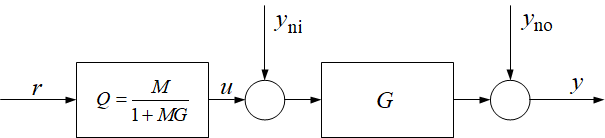

According to this structure the Q controller can be designed in open loop which may allow the use of simpler and more transparent tools. A warning however that while this simplified structure ensures reference signal tracking, it does not reflect the effect of the disturbances accurately.

The best controller choice would be $Q=G^{-1}$. If the Youla parameter is the inverse of the transfer function of the process, then the resulting transfer function of the closed loop would be unity. Nevertheless, it should be mentioned that generally this transfer function is not realisable and/or may require input signals which are too aggressive.

To ensure effective disturbance rejection the control system is enhanced with internal model control as shown in the figure below. Here only the output disturbance *yn* is indicated.

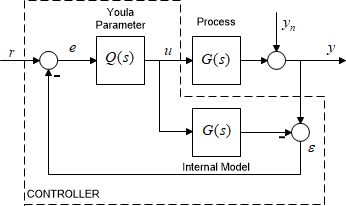

If there is no disturbance and the internal model is exactly the same as the process, then the value of the feedback signal $\varepsilon$ is zero, and the reference signal tracking is determined by the forward path of the open loop. The feedback will ensure disturbance rejection and eliminates the effect of plant-model mismatch as well.

If there is no mismatch, then


$$u=Q\left(r-y_n \right)$$



$$y=\textrm{Gu}+y_n =\textrm{GQr}-\textrm{GQ}y_n +y_n =\textrm{Tr}+\left(1-T\right)y_n$$


The eqiuvalent block diagram is given in the figure below.

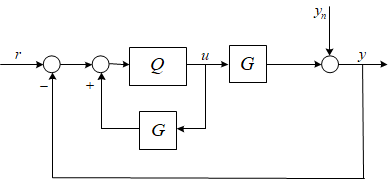

This block diagram can be transformed to a usual feedback system where the series controller is expressed with the Youla parameter as shown in the next figure.

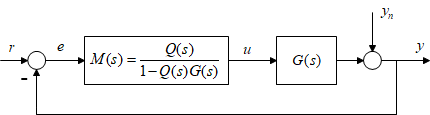

## 2. Controller design

As it was already mentioned the best controller choice would be $Q=G^{-1}$. If the Youla parameter is the inverse of the transfer function of the process, then the resulting transfer function between the output and the reference signal would be unity, although in practise such a choice is not realisable as the transfer function of a process cannot be inverted.

- Dead time is non-invertible, as its inverse is not realizable (that would require seeing into the future).

- A transfer function cannot be inverted if the degree of its denominator polynomial is higher than the degree of its nominator polynomial (which is normal) as this leads to impulses and other non-implementable signals.

- A non-minimum phase transfer function, which contains right side zeros is non-invertible, as its inversion would introduce unstable poles in the transfer function of the controller and thus potentially partially hidden unstable modes within the control loop.

Hence, given plant inversion is not possible, the best thing is to separate the transfer function of the model of the plant to the product of its invertible $G_+ \left(s\right)$ and non-invertible $G_- \left(s\right)$ parts. The static gain of $G_- \left(s\right)$ should be 1 to ensure accurate reference signal tracking in steady state. Thus $G_- \left(s=0\right)=1\ldotp$


$$G\left(s\right)=G_+ \left(s\right)G_- \left(s\right)$$


The Youla parameter performs the inverse of the invertible part of the transfer function of the model of the process.


$$Q=G_+^{-1}$$


The control system now is shown in the figure below.

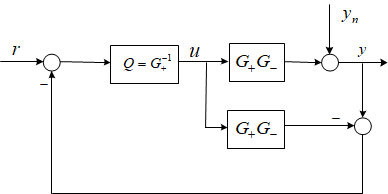

The dynamics of reference signal tracking and disturbance rejection is the same. Several times it is required that the dynamics of reference signal tracking and the dynamics of disturbance rejection be different. This can be ensured by introducing filters $R_r$(s) and $R_n \left(s\right)$ according to the figure below. The static gain of the filters should be 1. The figure below shows the modified structure. This structure is called also 2DF (Two Dimension of Freedom) structure, as the dynamics of reference signal tracking and that of disturbance rejection are different.

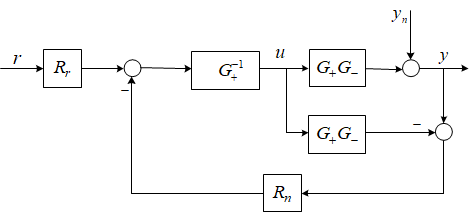

Reference signal tracking is given by relationship $R_r \left(s\right)G_-$(s)  and disturbance rejection by relationship $1-R_n \left(s\right)G_- \left(s\right)$. This block diagram can be redrawn according to the following figure.

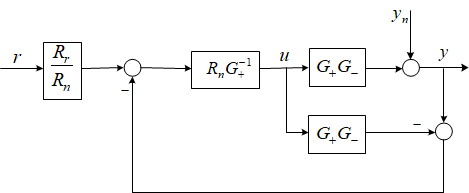

The Youla parameter is now:


$$Q=R_n G_+^{-1}$$


Restructuring the figure the conventional feedback system is obtained as shown in the figure below, where the series controller can be given as:


$$M=\frac{R_n G_+^{-1} }{1-R_n G_- }=\frac{Q}{1-\textrm{QG}}$$


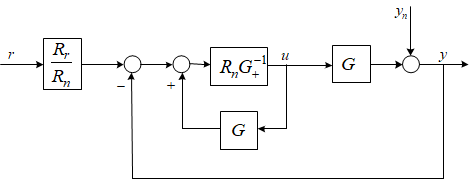

With the filters the relations among the signals are expressed as:


$$\left\lbrack \begin{array}{c}
u\\
e\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{R_r }{R_n }Q & -Q\\
\frac{R_r }{R_n }\left(1-\textrm{QG}\right) & -\left(1-\textrm{QG}\right)\\
\frac{R_r }{R_n }\textrm{QG} & 1-\textrm{QG}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{R_r }{R_n }Q & -Q\\
\frac{R_r }{R_n }S & -S\\
\frac{R_r }{R_n }T & S
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
y_n 
\end{array}\right\rbrack$$


*The effect of the filters is threefold*. With different reference and disturbance filters the dynamics of reference signal tracking and the dynamics of disturbance rejection will be different, the control system will have two-degrees of freedom (2DF). The reference signal filter affects the maximum value of the control signal. With the filters the robustness of the control system can also be influenced (this latter topic is not analysed here).

*Summarising the controller design*: The transfer function of the process is separated into the invertible and non-invertible parts. The reference and disturbance filters should be chosen. For realisability their orders should be chosen equal to the order of the system to be controlled. Then the Q parameter is calculated and the control system is realised in an IMC structure or the controller is transformed to the usual feedback form. 

## **3. Examples**

This section will give a number of examples of using the Youla parameter to support enhanced controller design, that is, beginning from an existing compensator, how can we enhance the loop properties by making systematic use of higher order solutions?

**Example 1. Youla parameterised control of a first order system with dead time** 

The transfer function of the process is


$$G\left(s\right)=\frac{2}{1+20s}e^{-10\;s}$$


For this system a PI controller with pole cancellation technique has been designed which ensures  ~60° phase margin in file **PID_controller_design with_pole_cancellation.mlx**. The designed controller is:

$M_{\textrm{PI}} \left(s\right)=0\ldotp 52334\cdot \frac{s+0\ldotp 05}{s}$.

The loop transfer function is $L\left(s\right)=M_{\textrm{PI}} \left(s\right)G\left(s\right)=\frac{0\ldotp 052334}{s}e^{-10s}$

With this controller the settling time is ~60s.

---------------------------------------------------------

Design a Youla parameterised controller for the process with the reference filter $R_r \left(s\right)=\frac{1}{1+5s}$ and disturbance filter $R_n \left(s\right)=\frac{1}{1+2s}$. These filters determine the dynamics of reference signal tracking and disturbance rejection. Give the *Q* Youla parameter. Determine and plot the output signal for step reference signal supposing no output disturbance. Give also the control signal. Determine and plot the output signal for step output disturbance supposing no reference signal. Give also the control signal. Compare reference signal tracking of the control system with the Youla parameterised controller and with the PI controller. 

disp('BELOW IS SECTION 1')

BELOW IS SECTION 1


disp('EXAMPLE 1: YOULA PARAMETERISED CONTROL OF A FIRST ORDER SYSTEM WITH DEAD TIME')

EXAMPLE 1: YOULA PARAMETERISED CONTROL OF A FIRST ORDER SYSTEM WITH DEAD TIME


s=zpk('s');
Gp=2/(1+20*s);
disp('The process')

The process


Gm=exp(-10*s);
G=Gp*Gm

G =
 
                 0.1
  exp(-10*s) * --------
               (s+0.05)
 
Continuous-time zero/pole/gain model.
Model Properties


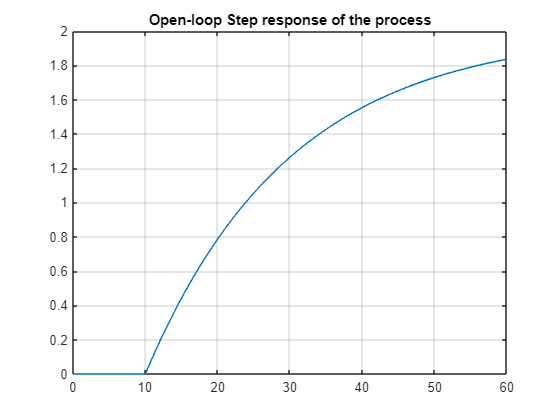

t=0:0.5:60;
ys=step(G,t);
plot(t,ys),grid
title('Open-loop Step response of the process')


disp('The filters')

The filters


Rr=1/(1+5*s)

Rr =
 
    0.2
  -------
  (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


Rn=1/(1+2*s)

Rn =
 
    0.5
  -------
  (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The YOULA parameter')

The YOULA parameter


Q=minreal(Rn/Gp,0.001)

Q =
 
  5 (s+0.05)
  ----------
   (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The transfer function between the output and the reference signal')

The transfer function between the output and the reference signal


T=minreal((Rr/Rn)*Q*G,0.001)

T =
 
                 0.2
  exp(-10*s) * -------
               (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The transfer function between the control signal and the reference signal')

The transfer function between the control signal and the reference signal


U=minreal((Rr/Rn)*Q,0.001)

U =
 
  2 (s+0.05)
  ----------
   (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


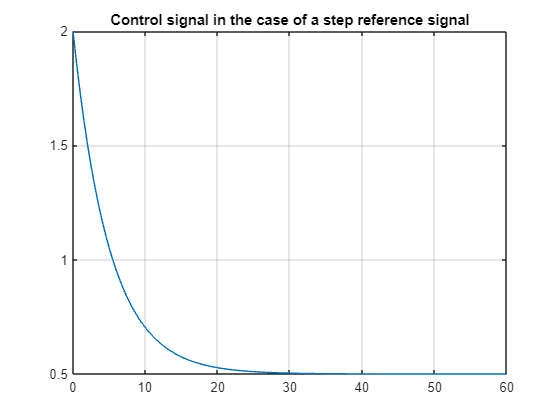

y=step(T,t);

%Closed loop step response for step reference input
u=step(U,t);
plot(t,u),grid
title('Control signal in the case of a step reference signal')

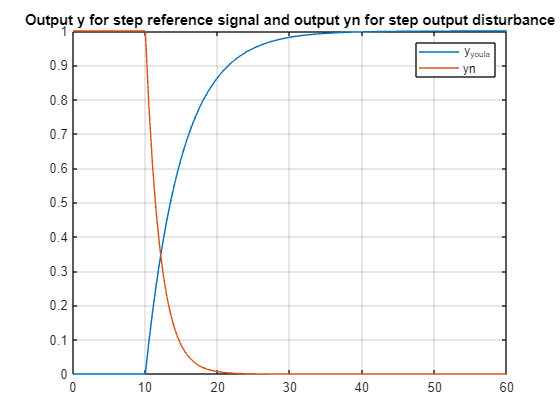


%Closed loop step response for step output disturbance
yn=step(1-Q*G,t);
plot(t,y,t,yn),grid
legend('y_{youla}','yn')
title('Output y for step reference signal and output yn for step output disturbance')

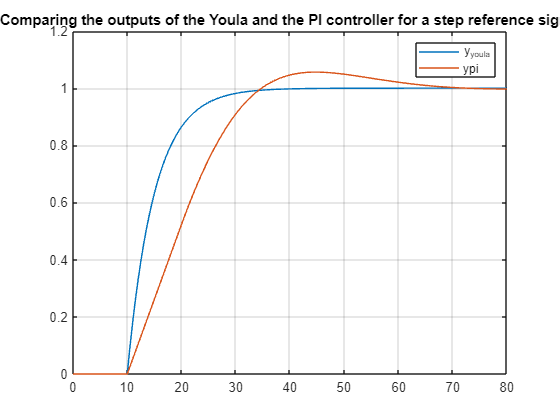


%Comparison of the Youla controller with the PI controller
%The open loop with the PI controller
Lpi=(0.052334/s)*exp(-10*s);
%The closed loop
Tpi=Lpi/(1+Lpi);
%The response for step reference signal
t1=0:0.5:80;
ypi=step(Tpi,t1);
y1=step(T,t1);
plot(t1,y1,t1,ypi),grid
legend('y_{youla}','ypi')
title('Comparing the outputs of the Youla and the PI controller for a step reference signal')

It is seen that:

- the control ensures a faster settling than that of the process itself. 

- the disturbance rejection is faster than reference signal tracking because of the different filters.

- the settling process is faster with the Youla parameterised controller than with the PI controller. Especially in case of a big dead time the Youla design provides much faster behaviour than the PID controllers.

#### Student private study

*Task1*. Check the control behaviour with different filters.

*Task2*. Check the control behaviour in case of dead time mismatch: The real dead time is 10, the considered model dead time is 12.

*Task3*. The transfer function of the process is


$$G\left(s\right)=\frac{1}{\left(1+5s\right)\left(1+10s\right)}e^{-30s}$$


Design a Youla parameterised controller with filters $R_r =R_n =\frac{1}{{\left(1+s\right)}^2 }$; Then choose the input filter as $R_r =\frac{1}{\left(1+5s\right)\left(1+s\right)}$.

Give the Youla parameter. Plot the output signal for step reference input and for step reference disturbance. Plot also the corresponding control signals. Analyse the behaviour of the system with different filters.  Design also a PIPD controller for the system for phase margin ~60° and compare the behaviour of the control system with the Youla and the PIPD controller. 

**Example 2. Youla parameterised control of a third order system**

The transfer function of the process is


$$G\left(s\right)=\frac{1}{\left(1+2s\right)\left(1+5s\right)\left(1+10s\right)}$$


Design a Youla parameterised controller with filters 

$R_r =\frac{1}{{\left(1+2s\right)}^3 }$; $R_n =\frac{1}{{\left(1+4s\right)}^3 }$

disp('BELOW IS SECTION 2')

BELOW IS SECTION 2


disp('EXAMPLE 2: YOULA PARAMETERISED CONTROL OF A THIRD ORDER SYSTEM')

EXAMPLE 2: YOULA PARAMETERISED CONTROL OF A THIRD ORDER SYSTEM


s=zpk('s');
disp('The process')

The process


G=1/((1+2*s)*(1+5*s)*(1+10*s))

G =
 
           0.01
  -----------------------
  (s+0.5) (s+0.2) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


Gp=G;
disp('output of the process for step referebce signal')

output of the process for step referebce signal


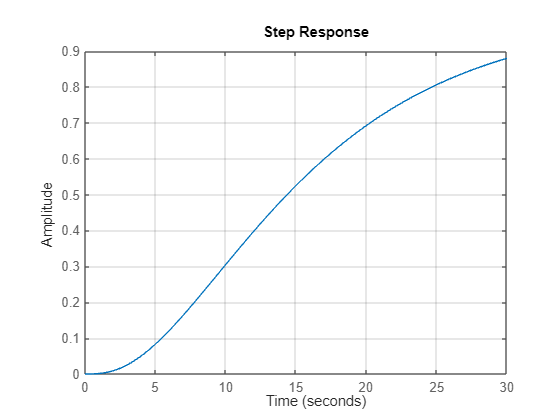

t=0:0.1:30;
step(t,G),grid

disp('The filters')

The filters


Rn=1/(1+4*s)^3

Rn =
 
   0.015625
  ----------
  (s+0.25)^3
 
Continuous-time zero/pole/gain model.
Model Properties


Rr=1/(1+2*s)^3

Rr =
 
    0.125
  ---------
  (s+0.5)^3
 
Continuous-time zero/pole/gain model.
Model Properties


%Youla design
disp('YOULA PARAMETER')

YOULA PARAMETER


Q=minreal(Rn/Gp,0.001)

Q =
 
  1.5625 (s+0.5) (s+0.2) (s+0.1)
  ------------------------------
            (s+0.25)^3
 
Continuous-time zero/pole/gain model.
Model Properties


T=minreal((Rr/Rn)*Q*G,0.001);
U=minreal((Rr/Rn)*Q,0.001);
disp('The output signal')

The output signal


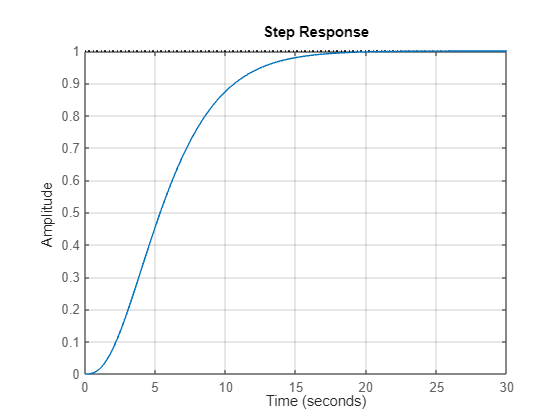

step(t,T),grid

disp('The control signal')

The control signal


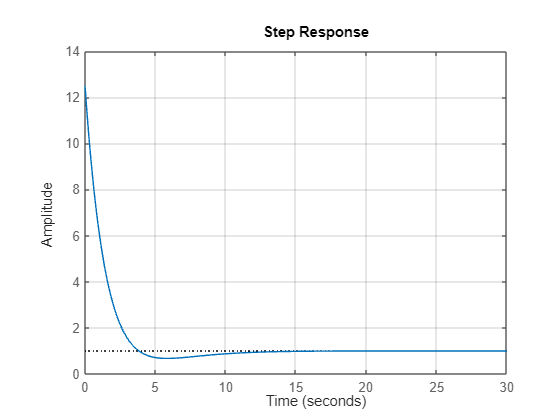

step(t,U),grid

It is seen that the settling of the control system is much faster than the settling of the process itself on the price of overexcitation in the control signal.

**Example 3. Youla parameterised control of a non-minimum phase process**

The transfer function of the process is


$$G\left(s\right)=\frac{1-s}{\left(1+s\right)\left(1+2s\right)}$$


Design a Youla parameterised controller with filters 

$R_r =\frac{1}{{\left(1+0\ldotp 8s\right)}^2 }$; $R_n =\frac{1}{\left(1+0\ldotp 2s\right)\left(1+0\ldotp 5s\right)}$.

The numerator of the model of the process can not be cancelled, as it would introduce an unstable pole in the controller.

disp('BELOW IS SECTION 3')

BELOW IS SECTION 3


disp('EXAMPLE 3: YOULA PARAMETERISED CONTROL OF A NON-MINIMUM PHASE PROCESS')

EXAMPLE 3: YOULA PARAMETERISED CONTROL OF A NON-MINIMUM PHASE PROCESS


s=zpk('s');
disp('The process')

The process


G=(1-s)/((1+s)*(1+2*s))

G =
 
   -0.5 (s-1)
  -------------
  (s+1) (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('Step response of the process')

Step response of the process


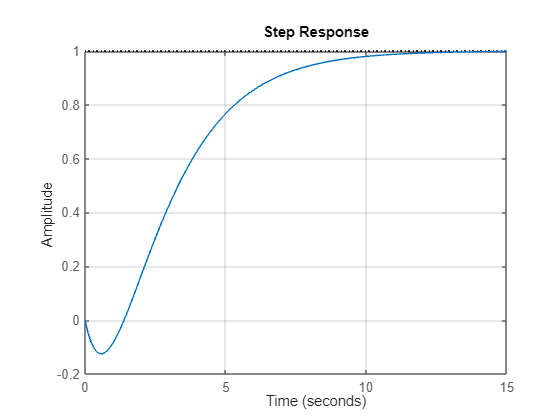

t=0:0.1:15;
step(t,G),grid

disp('The invertible part of the model of the process')

The invertible part of the model of the process


Gp=1/((1+s)*(1+2*s))

Gp =
 
       0.5
  -------------
  (s+1) (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The filters')

The filters


Rn=1/((1+0.2*s)*(1+0.5*s))

Rn =
 
      10
  -----------
  (s+5) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


Rr=1/(1+0.8*s)^2

Rr =
 
    1.5625
  ----------
  (s+1.25)^2
 
Continuous-time zero/pole/gain model.
Model Properties


%Youla design
disp('YOULA PARAMETER')

YOULA PARAMETER


Q=minreal(Rn/Gp,0.001)

Q =
 
  20 (s+1) (s+0.5)
  ----------------
    (s+5) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


T=minreal((Rr/Rn)*Q*G,0.001);
U=minreal((Rr/Rn)*Q,0.001);
disp('The output signal')

The output signal


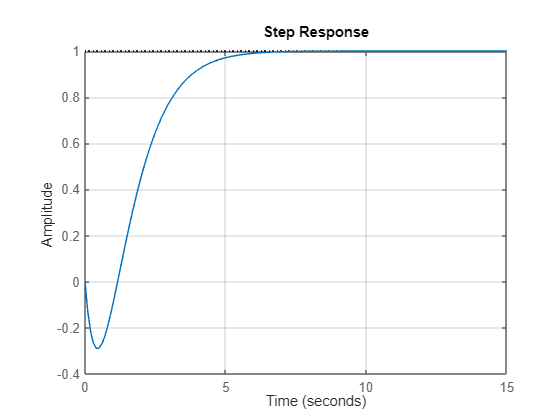

step(t,T),grid

disp('The control signal')

The control signal


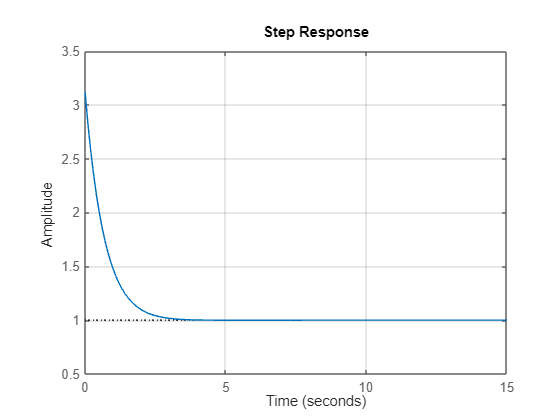

step(t,U),grid

It is seen that the settling of the control system became faster then that of the model of the process. The non-minimum-phase character remained.

*Task*: Analyse the behaviour of the control system with different filters.

## Summary

The Youla parameter gives the transfer function between the control signal and the reference signal in a control system. With the Youla parameter the controller can be designed in open loop, and enhancing the control structure with IMC disturbance rejection can also be ensured. For realisability the transfer function of the process is separated to invertible and non-invertible parts, and in the controller only the inverse of the invertible part is considered. Introducing filters the dynamics of reference signal tracking and disturbance rejection can be different.